clear, close all
clc

[clarinet, fs] = audioread(strcat(pwd, '\Original_AudioFiles\Clarinet_2.wav'));
piano = audioread(strcat(pwd, '\Original_AudioFiles\Piano_2.wav'));
viola = audioread(strcat(pwd, '\Original_AudioFiles\Viola_2.wav'));
sine = audioread(strcat(pwd, '\Original_AudioFiles\Sine_2.wav'));

c3 = 130.813 * 1; % [Hz]
bpm = 120;
durNote = 60 / bpm; % Duration of each note [s]
selectedPart = durNote * 5 * fs; % 5 notes selected

%t = 0 : 1 / fs : selectedPart;



wind = 2 ^12 % Window size

wind = 4096

nlap = 2 ^11 % Overlap 

nlap = 2048

nfft = 2 ^ 13 % Number of FFT points

nfft = 8192

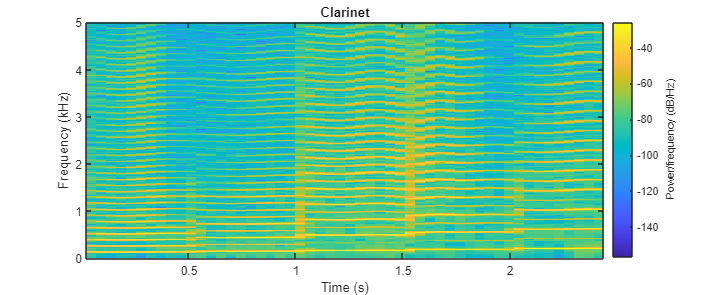


widthGraph = 1000;
heightGraph = 400;
x0 = 10;
y0 = 10;

fmax = 5;

spectrogram(clarinet(1 : selectedPart),wind,nlap,nfft,fs,'yaxis')
set(gcf,'position', [x0,y0,widthGraph,heightGraph]);
ylim([0 fmax])
title('Clarinet')

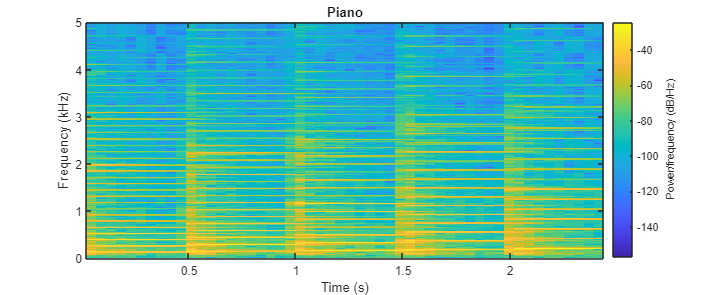


spectrogram(piano(1 : selectedPart),wind,nlap,nfft,fs,'yaxis')
set(gcf,'position', [x0,y0,widthGraph,heightGraph]);
ylim([0 fmax])
title('Piano')

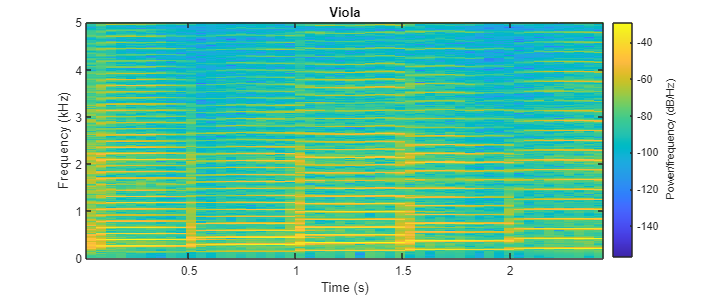


spectrogram(viola(1 : selectedPart),wind,nlap,nfft,fs,'yaxis')
set(gcf,'position', [x0,y0,widthGraph,heightGraph]);
ylim([0 fmax])
title('Viola')

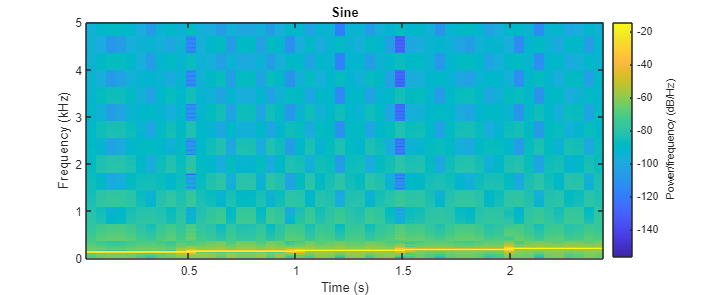


spectrogram(sine(1 : selectedPart),wind,nlap,nfft,fs,'yaxis')
set(gcf,'position', [x0,y0,widthGraph,heightGraph]);
ylim([0 fmax])
title('Sine')

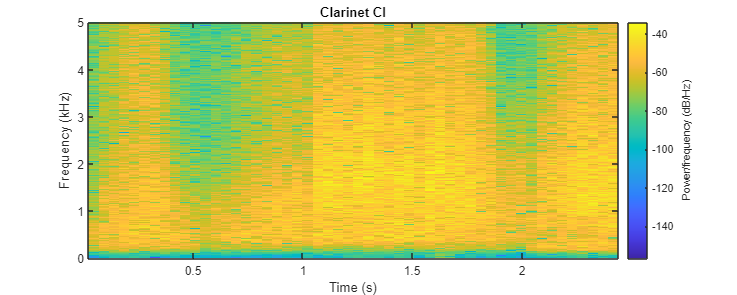

clarinetCI = audioread(strcat(pwd, '\Original_AudioFiles\CI_Emulations\CIClarinet_2.wav'));
pianoCI = audioread(strcat(pwd, '\Original_AudioFiles\CI_Emulations\CIPiano_2.wav'));
violaCI = audioread(strcat(pwd, '\Original_AudioFiles\CI_Emulations\CIViola_2.wav'));
sineCI = audioread(strcat(pwd, '\Original_AudioFiles\CI_Emulations\CISine_2.wav'));

spectrogram(clarinetCI(1 : selectedPart),wind,nlap,nfft,fs,'yaxis')
set(gcf,'position', [x0,y0,widthGraph,heightGraph]);
ylim([0 fmax])
title('Clarinet CI')

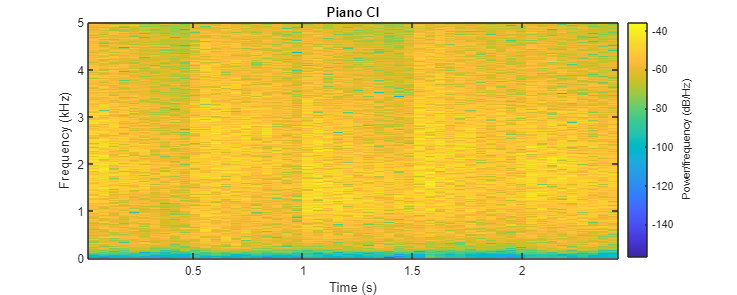


spectrogram(pianoCI(1 : selectedPart),wind,nlap,nfft,fs,'yaxis')
set(gcf,'position', [x0,y0,widthGraph,heightGraph]);
ylim([0 fmax])
title('Piano CI')

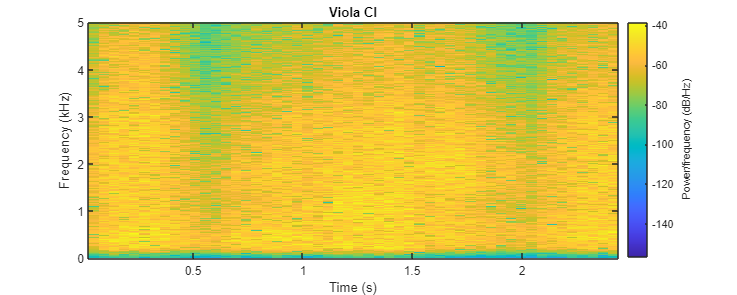


spectrogram(violaCI(1 : selectedPart),wind,nlap,nfft,fs,'yaxis')
set(gcf,'position', [x0,y0,widthGraph,heightGraph]);
ylim([0 fmax])
title('Viola CI')

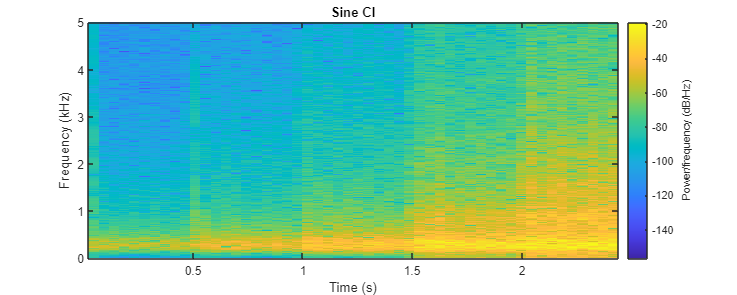


spectrogram(sineCI(1 : selectedPart),wind,nlap,nfft,fs,'yaxis')
set(gcf,'position', [x0,y0,widthGraph,heightGraph]);
ylim([0 fmax])
title('Sine CI')